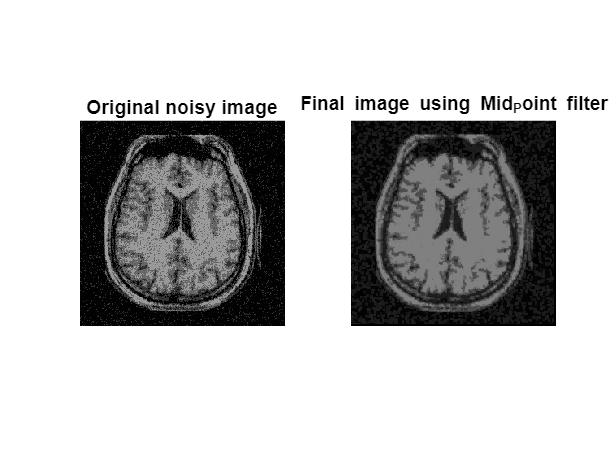

clc;clear;close all;
i=uigetfile('*.*');
I=imread(i);
J=rgb2gray(I);
subplot(1,2,1);
imshow(I);title("Original noisy image");
[rows,columns]=size(J);
K=padarray(J,[1,1],0);
L=zeros(rows,columns);
for r=2:rows-1
    for c=2:columns-1
        filt=[K(r,c),K(r-1,c),K(r+1,c),K(r,c-1),K(r,c+1),K(r-1,c-1),K(r-1,c+1),K(r+1,c-1),K(r+1,c+1)];
        y1=min(filt);
        y2=max(filt);
        x=(y1+y2)./2;
        L(r-1,c-1)=x;
    end
end
subplot(1,2,2);
M=uint8(L);
imshow(M );title("Final image using Mid_Point filter");